# 2D Inversely designed 1x2 Mode Division Multiplexer

**Photonic inverse-design** uses an end-to-end design philosophy, optimizing the structure to maximize the coupling efficiency between the actual output field and target field. The distribution of relative permittivity, $\varepsilon_r$, of structure, based on gradient-based algorithms, is updated iteratively during the optimization process[1–3]. Photonic inverse-design method can provide unconventional, irregular, counterintuitive structures with previously unattainable functionality, or even higher performance and smaller footprints than traditional devices, which the traditional design method is unable to achieve.

### Step 0: Global settings

The simulation begins with the initialization of a `Model2D` instance, followed by defining the global settings. The working plane is set to the $\mathit{\mathbf{x}}-\mathit{\mathbf{y}}$** plane** as default. 

modelMUX = Model2D.initialize();

Model2D: Object Reset and Initialized


The core material is **silicon** while the surrounding cladding is **silicon dioxide**.

eps_core = 3.4712^2; % Silicon (core)
eps_clad = 1.5^2; % Silicon dioxide (cladding)
modelMUX.setBackground('eps_r', eps_clad);

### Step 1: Input `.gds` and build up device

GDSII is a widely adopted industry-standard format for the design, simulation, and fabrication of integrated photonic devices. Our toolbox supports direct import of `.gds` files, enabling users to define device geometries from standard layout designs.

The width of the input port is 750 nm, and two output ports are 480 nm. The central region has a footprint of 3.63 𝜇m × 3.63 𝜇m.

% inverse-designed Si structure
gdspath = fullfile(pwd, '.\MUX_21.gds');
modelMUX.addDevice(1);
modelMUX.setDevice(1).setGeometry('GDSII', gdspath);


Library name  : LIB
Creation date : 2025-2-14, 14:16:09
User unit     : 1e-06 m
Database unit : 1e-09 m

Read time  : 00:00:00.000
Structures : 1
Elements   : 1



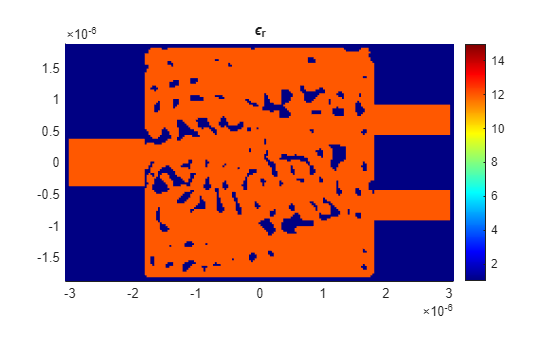

modelMUX.setDevice(1).setMaterial(eps_core);

% assamble and display entire device
modelMUX.assembleDevice;
modelMUX.device.dispImg;

### Step 2: Mesh grid

In our original inverse-design code, we defined grids as below. To preserve as many features as possible when converting `.gds` files to MATLAB, we have implemented the same grid structure here.

% mesh grid
Nx = 201; dx = 30e-9;
Ny = 201; dy = 30e-9;
modelMUX.setMesh([Nx, Ny], [dx, dy]); % the center of coordinates are 0 as default

% mesh device
modelMUX.meshDevice;

### Step 3: FDFD solver settings

This inversely designed device was optimized at wavelength of **1.55 µm**, which is commonly used in optical communications, and **TE mode** polarization. 

modelMUX.setWavelength(1.55e-6); % at 1.55 um wavelength
modelMUX.setSolver("Scattering", 'TE'); % 'Scattering' solver, 'TE' mode
modelMUX.setBoundary('x', 'PML', 10); % PML boundary condition for both x and y boundaries
modelMUX.setBoundary('y', 'PML', 10);

###  Step 4: Input port and source

The fundamental and second TE eigenmodes of input port are injected as source.

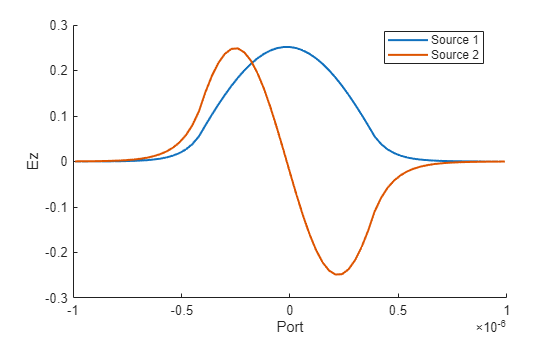

modelMUX.addPort('+x', -2.5e-6, [-1e-6, 1e-6]); % unit: m

num_mode = [1,2]; % fundamental mode
modelMUX.addSource("EigenMode", num_mode);
modelMUX.cfg.source.dispProfile('Ez');

### Step 5: 2D scattering simulation

modelMUX.dispInfo; % check configuration before solving

=== Model2D Information ===
Wavelength   : 1.550e-06 m
Plane Label  : xy
Background   : eps_r=2.250, mu_r=1.000
Mesh         : x: N=201, d=3.000e-08 m
               y: N=201, d=3.000e-08 m
Solver       : Scattering
BC (x)     : PML, thickness=10
BC (y)     : PML, thickness=10
Source Polarization : TE
Source Port         : dir=+x
                      position (x) = -2.500e-06 m
                      span (y)     = [-1.000e-06, 1.000e-06] m


modelMUX.solveModel;

Model object has been solved successfully.


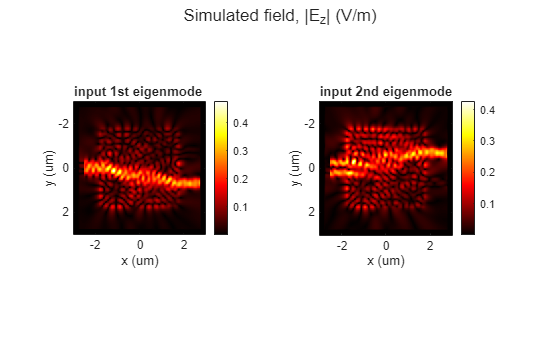

results = modelMUX.exportResults;

figure;
subplot(1,2,1); sgtitle('Simulated field, |E_z| (V/m)')
imagesc(results.x*1e6, results.y*1e6, abs(results.Ez(:,:,1)).');
xlabel('x (um)'), ylabel('y (um)'); axis image;
title('input 1st eigenmode ');
colormap hot; colorbar;
subplot(1,2,2);
imagesc(results.x*1e6, results.y*1e6, abs(results.Ez(:,:,2)).');
xlabel('x (um)'), ylabel('y (um)'); axis image;
title('input 2nd eigenmode');
colormap hot; colorbar;

As we deigned, modes are splitted into two output ports.

### Reference

[1] Molesky, S., Lin, Z., Piggott, A. Y., Jin, W., Vucković, J., & Rodriguez, A. W. (2018). Inverse design in nanophotonics. *Nature Photonics*, *12*(11), 659-670. 

[2] Piggott, A. Y., Lu, J., Lagoudakis, K. G., Petykiewicz, J., Babinec, T. M., & Vučković, J. (2015). Inverse design and demonstration of a compact and broadband on-chip wavelength demultiplexer. *Nature photonics*, *9*(6), 374-377.

[3] Su, L., Vercruysse, D., Skarda, J., Sapra, N. V., Petykiewicz, J. A., & Vučković, J. (2020). Nanophotonic inverse design with SPINS: Software architecture and practical considerations. *Applied Physics Reviews*, *7*(1).